This file is used to check the correct way to excite the expected mode in a wave guide.

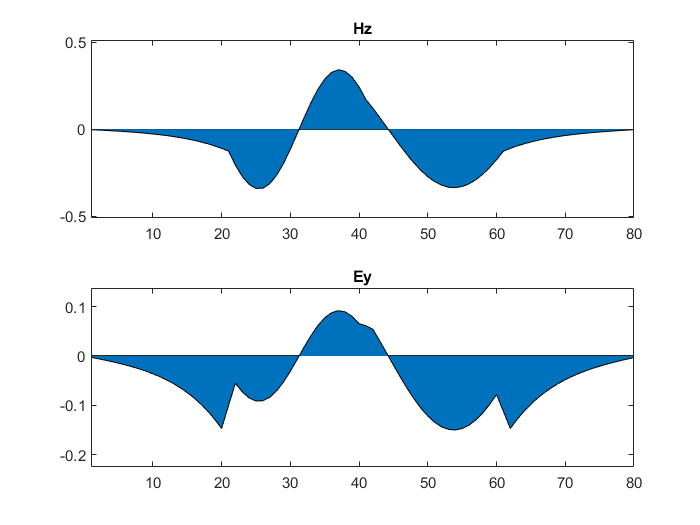

Mode number: 3
kx : 0.201
Error of calculation: 0.000
Power: 1.000


eps_cut = [ones(1, 20), 5*ones(1,20), 3*ones(1, 20), 1*ones(1, 20)];
% eps_cut = [ones(1,30), 12.25*ones(1,20), ones(1, 30)];
eps = repmat(eps_cut, 1000, 1); % struct the simulated region
omega = 0.15;

% set the input here
[input.Ey, input.Hz, input.k] = wave_mode(eps_cut, omega, 3, 'pos'); 

% simulate the field under the given input, and we divide eps_y here
[Ex, Ey, Hz] = fdfd_2d(eps, input, omega, 'pml');

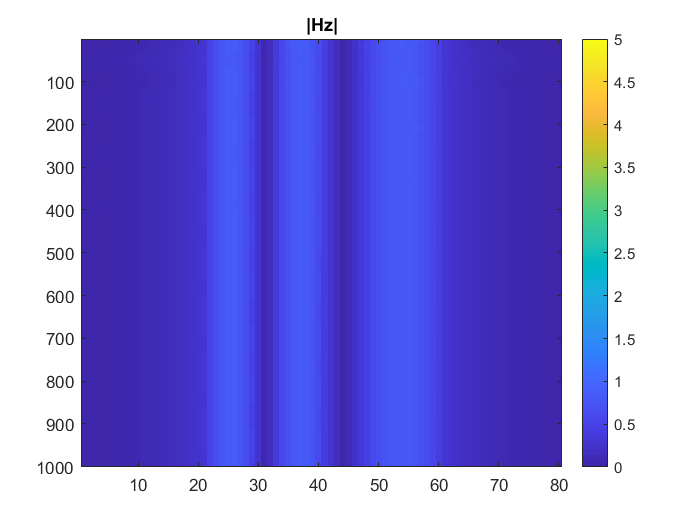

% draw the image
close all
imagesc(abs(Hz))
colorbar
caxis([0, 5])
title('|Hz|')

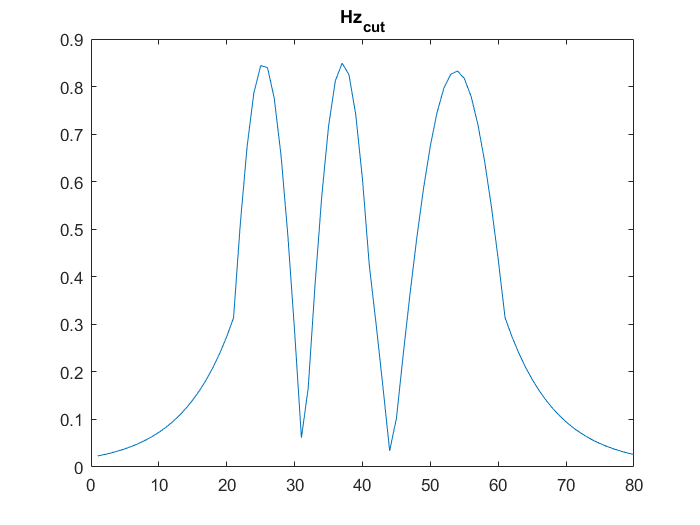


plot(abs(Hz(500, :)))
title('Hz_{cut}')

Mode number: 1
kx : 0.309
Error of calculation: 0.000
Power: 1.000
Mode number: 2
kx : 0.249
Error of calculation: 0.000
Power: 1.000
Mode number: 3
kx : 0.201
Error of calculation: 0.000
Power: 1.000
Mode number: 4
kx : 0.145
Error of calculation: 0.000
Power: 1.000
Mode number: 5
kx : 0.107
Error of calculation: 0.000
Power: 1.000


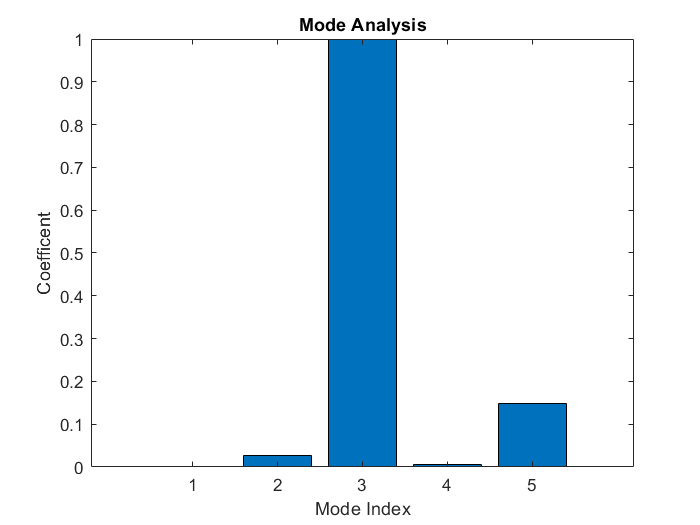

% do the mode analysis
mode_analysis(Hz(500, :), eps_cut, omega, [1:5]);

% simulate the field under the given input, and we don't divide eps_y here
[Ex, Ey, Hz] = fdfd_2d(eps, input, omega, 'pml');

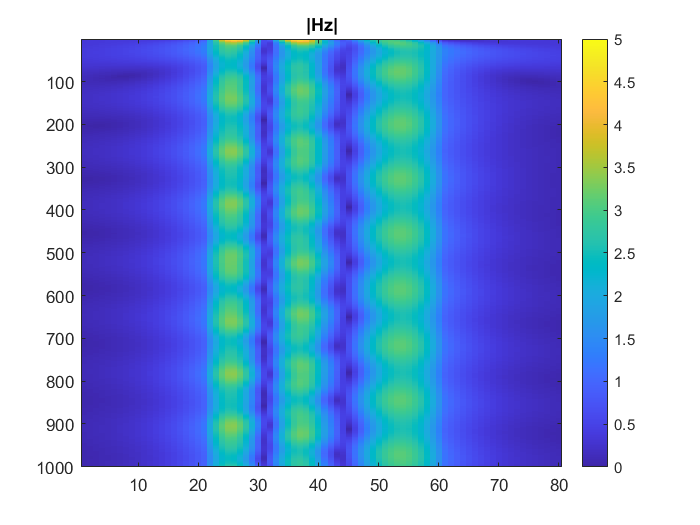

% draw the image
close all
imagesc(abs(Hz))
title('|Hz|')
caxis([0,5])
colorbar

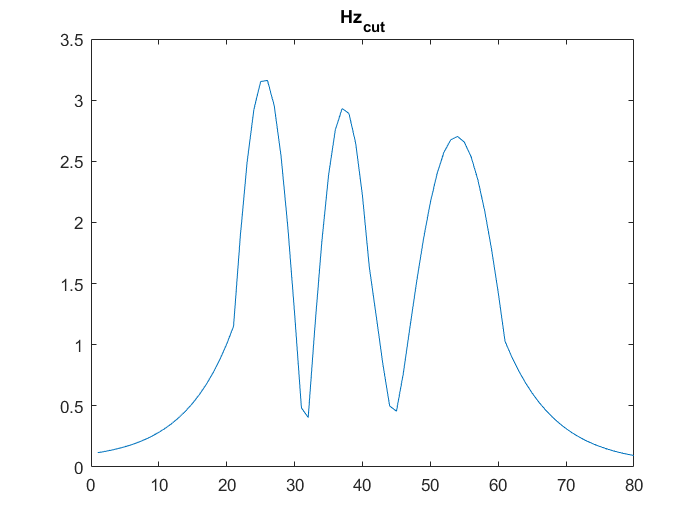


plot(abs(Hz(500, :)))
title('Hz_{cut}')

Mode number: 1
kx : 0.309
Error of calculation: 0.000
Power: 1.000
Mode number: 2
kx : 0.249
Error of calculation: 0.000
Power: 1.000
Mode number: 3
kx : 0.201
Error of calculation: 0.000
Power: 1.000
Mode number: 4
kx : 0.145
Error of calculation: 0.000
Power: 1.000
Mode number: 5
kx : 0.107
Error of calculation: 0.000
Power: 1.000


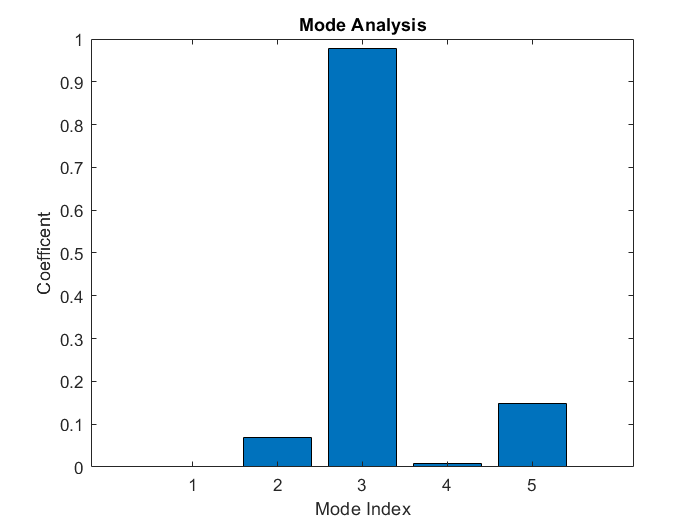

% do the mode analysis
mode_analysis(Hz(500, :), eps_cut, omega, [1:5]);

problem:

-  The operator in wave_mode seems non-hermitian

- It seems we should divide eps_y

- Why \omega = 1 cannot excite the mode

- |Hz| should be uniform or oscillating

- The staggered gird and eps_x, eps_y